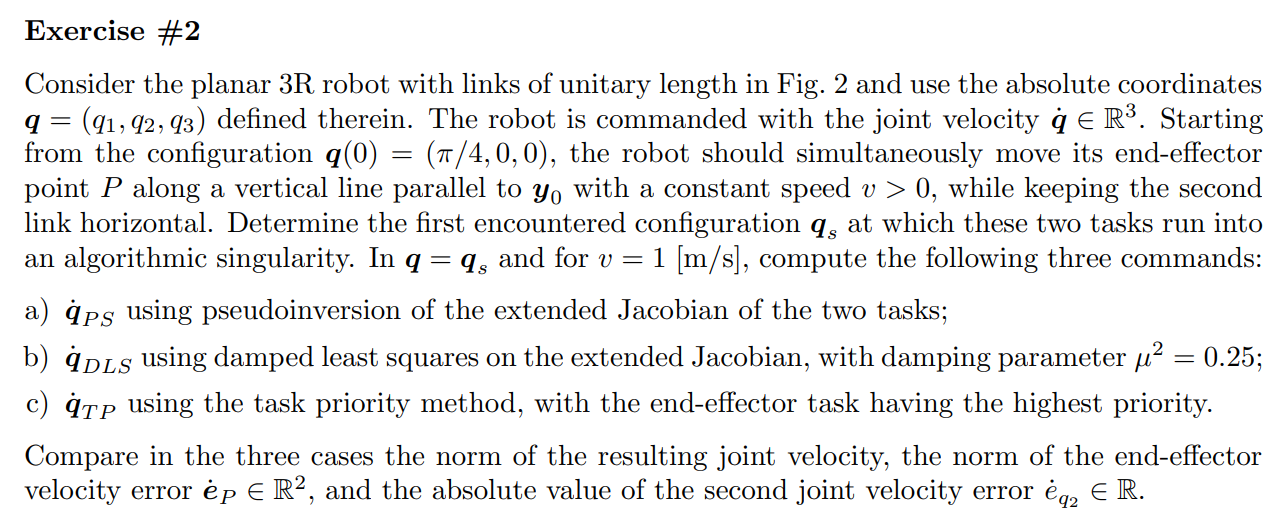

syms q1 q2 q3 v real;
q=[q1;q2;q3]

$$q = \left(\begin{array}{c} q_{1}\\ q_{2}\\ q_{3} \end{array}\right)$$

we-re considering the 3R planar robot commanded in joint velocity, starting from $q(0)=\left(\frac{\pi}{4} \ 0 \ 0 \right)$ and the robot should perform two different task:

- Move its end effector along the vertical line parallel to $y_0$ starting from *q*(0) with constant sped v>0. This is teh **Primary task **that has dimention $m_1=2$ because it invole the cartesian position and in particolar it consider the task velocity $\dot{r_1}=(0 \ 1 )^T v$ , and form the direct kinematic we have that the position $\mathbf{f_1(q)=r_1=(P_x \ P_y)}$ is given by: ( considering absolute coordinates wrt to $x_0$ axis )

Px=cos(q1)+cos(q2)+cos(q3)

$$Px = \cos\left(q_{1}\right)+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)$$

Py=sin(q1)+sin(q2)+sin(q3)

$$Py = \sin\left(q_{1}\right)+\sin\left(q_{2}\right)+\sin\left(q_{3}\right)$$

r1=[Px;Py];
f1=r1

$$f1 = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)\\ \sin\left(q_{1}\right)+\sin\left(q_{2}\right)+\sin\left(q_{3}\right) \end{array}\right)$$

r1_dot_des=[0;1]*v

$$r1\_dot\_des = \left(\begin{array}{c} 0\\ v \end{array}\right)$$

- We have a degree of redundancy equal to $d_{red}=N-M=3-2$ . We chose to add 1 auxiliary task, so *S=*1. This task consist in keep the second link horizontal, this involves only $q_2$ so the task dimention in this case is $m_2=1$. In fact we are considering $f_y(q)=y \quad \to \quad q_2(t)=0$.  in particular we want:

r2_des=0

r2_des = 0

r2_dot_des=0

r2_dot_des = 0

f2=q2

$$f2 = q_{2}$$

and so the second function that we have to consider is $\mathbf{f_2(q)=r_2=q_2}$   and we want $r_2(t)=0 \to \dot{r}_2=0$

Note that now we have N=3 and M+S=3 so we have squared the porblem.

We have to study the evolution of the motion with these goals and find the first singularity that we encounter, so the first configuration in which we cannot follow the predefinited goals. **In order to do it we have to define the Augmented Jacobian**

J1=jacobian(f1,q);
J2=jacobian(f2,q);
JE_sym=[J1;J2]

$$JE\_sym = \left(\begin{array}{ccc} -\sin\left(q_{1}\right) & -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right)\\ \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right)\\ 0 & 1 & 0 \end{array}\right)$$

r_dot_des=[r1_dot_des;r2_dot_des]

$$r\_dot\_des = \left(\begin{array}{c} 0\\ v\\ 0 \end{array}\right)$$

Since the jacobian is a square matrix , out of a singularities, the joint velocity will be commanded in an unique way by the inverse of the jacobian so: 


$$\dot{q}=J_E^{-1}\dot{r}$$


So let's check if in q(0) we have singularities, because in this case we cannot invert the matrix but we have to use the pseudoinversion.

JE=subs(JE_sym,q,[pi/4;0;0]) 

$$JE = \left(\begin{array}{ccc} -\frac{\sqrt{2}}{2} & 0 & 0\\ \frac{\sqrt{2}}{2} & 1 & 1\\ 0 & 1 & 0 \end{array}\right)$$

rank(JE)

ans = 3

as we can see $rank(J_E)=3$ so it is non singular and we can apply $\dot{q}=J_A^{-1}(q)\dot{r_A}$ so:

q_dot_des_out_singularities=inv(JE)*r_dot_des

$$q\_dot\_des\_out\_singularities = \left(\begin{array}{c} 0\\ 0\\ v \end{array}\right)$$

So in q(0) in order to have an **instantanueous **motion that is on a line parallel to $y_0$ we have to move only $q_3$ counter clockwise. but if we think on it after this configuration we have the first joint that goes below $\frac{\pi}{4}$ and the third link conitnue to rotate counter clock-wise.

Now we have to understand which is the first configuration that provide a singularity. In order to do it we have to study the determinant of $J_E$. We are in singular configuration when we cannot do both the task togheter, so we wnat to find $q_{sing}$ such that $det(J_E)=0$ 

simplify(det(JE_sym))

$$ans = \sin\left(q_{1}-q_{3}\right)$$

We have to consider that this equation $det(J_E)=0$ has different solution and so we need to impose that the end effector is still on the right line  (with the second link horizontal $\to q_{2,sing}=0$)  and so $q_{sing}$ must be such that :


$$P_x(q_{sing})=cos(q_{1,sing})+cos(q_{2,sing})|_{q_{2,sing}=0}+cos(q_{3,sing})=P_x(q(0))=\frac{\sqrt{2}}{2}+2$$


Px_in_q0=subs(Px,q,[pi/4;0;0])

$$Px\_in\_q0 = \frac{\sqrt{2}}{2}+2$$

We have to consider these two equation at the same time imposing a system, so:

        eq1 = 0 == sin(q1-q3);
        eq2 = round((sqrt(2)/2)+2,4) == cos(q1)+1+cos(q3);
solutions = solve([eq1, eq2], [q1, q3]);
q1_sing=round(vpa(solutions.q1),4)

$$q1\_sing = -0.548$$

q3_sing=round(vpa(solutions.q3),4)

$$q3\_sing = -0.548$$

q_sing=[q1_sing;0;q3_sing]

$$q\_sing = \left(\begin{array}{c} -0.548\\ 0\\ -0.548 \end{array}\right)$$

Note that, the Jacobian related to the cartesian task is given by:

round(vpa(subs(J1,q,[q1_sing;0;q3_sing])),4)

$$ans = \left(\begin{array}{ccc} 0.521 & 0 & 0.521\\ 0.8536 & 1.0 & 0.8536 \end{array}\right)$$

Which has full rank=2, and the Jacobian related to the other task is  given by $(0 \ 1 \ 0)$ that has still rank=1.

So we have a pure **Algorithmic singularity **.

Now proceed to evaluate the next commanded joint velocity in this singular configuration using 3 different methods, using v=1$\left[ \frac{m}{s} \right]$ , we need also the jacobian evaluated in the singular configuration:

r_dot=[0;1;0];
JE_sing=round(vpa(subs(JE_sym,q,[q1_sing;0;q3_sing])),4)

$$JE\_sing = \left(\begin{array}{ccc} 0.521 & 0 & 0.521\\ 0.8536 & 1.0 & 0.8536\\ 0 & 1.0 & 0 \end{array}\right)$$

**PseudoInverse Method**:   We use the formula $\dot{q}=J_A^\#(q)\dot{r}$ where $\dot{r}=(0 \ 1 \ 0 )^T$

round(vpa(pinv(JE_sing)),4)

$$ans = \left(\begin{array}{ccc} 0.4097 & 0.3357 & -0.3357\\ -0.3498 & 0.2135 & 0.7865\\ 0.4097 & 0.3357 & -0.3357 \end{array}\right)$$

q_dot_pseudo=round(vpa(pinv(JE_sing)),4)*r_dot

$$q\_dot\_pseudo = \left(\begin{array}{c} 0.3357\\ 0.2135\\ 0.3357 \end{array}\right)$$

**damped least square (DLS)** metod using $\mu^2=0.25$

mu=0.5;

q_DLS_dot=round(transpose(JE_sing)*round(inv(JE_sing*transpose(JE_sing)+(eye(3)*mu^2)),4)*r_dot,4)

$$q\_DLS\_dot = \left(\begin{array}{c} 0.2959\\ 0.2199\\ 0.2959 \end{array}\right)$$

Note that the two joint velocities $\dot{q}_{PS}  $ and $\dot{q}_{DLS}$ are similar, they are different each other but as we can see they have rispectively the first and the third component equal.

**Task Priority,** where the first task in priority is following the cartesian path and the second task is keep the second link horizontal.

r_dot_des_first_task=[0;1];
r_dot_des_second_task=0;
J1_sing=round(subs(J1,q,q_sing),4)

$$J1\_sing = \left(\begin{array}{ccc} 0.521 & 0 & 0.521\\ 0.8536 & 1.0 & 0.8536 \end{array}\right)$$

J2_sing=round(subs(J2,q,q_sing),4)

$$J2\_sing = \left(\begin{array}{ccc} 0 & 1.0 & 0 \end{array}\right)$$

Projector1=round(eye(3)-pinv(J1_sing)*J1_sing,4)

$$Projector1 = \left(\begin{array}{ccc} 0.5 & 0 & -0.5\\ 0 & 0 & 0\\ -0.5 & 0 & 0.5 \end{array}\right)$$

term=J2_sing*Projector1   

$$term = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

Projector1

$$Projector1 = \left(\begin{array}{ccc} 0.5 & 0 & -0.5\\ 0 & 0 & 0\\ -0.5 & 0 & 0.5 \end{array}\right)$$

J2_sing 

$$J2\_sing = \left(\begin{array}{ccc} 0 & 1.0 & 0 \end{array}\right)$$

** ATTENZIONE SE VOGLIO CALCOLARE LA PSEUDOINVERSA DI UN VETTORE DI 0, QUESTA è IL VETTORE DI 0 TRASPOSTO, STESSO CONCETTO PER UNA MATRICE NON QUADRATA**

pseudo_inverse_term=[0;0;0]

pseudo_inverse_term =      0
     0
     0



q_dot_TP=round(pinv(J1_sing)*r_dot_des_first_task,4) + pseudo_inverse_term*(r_dot_des_second_task-J2_sing*pinv(J1_sing)*r_dot_des_first_task)

$$q\_dot\_TP = \left(\begin{array}{c} 0\\ 1.0\\ 0 \end{array}\right)$$

# 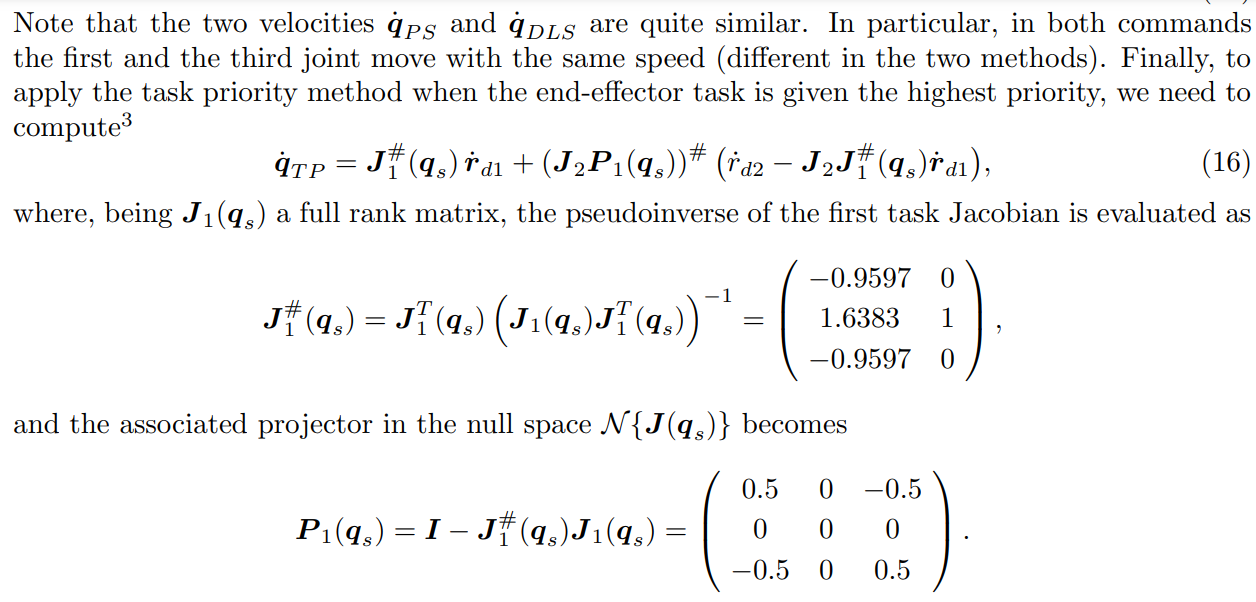

#